# Inrush inicial

clc;
clf;
clear all;

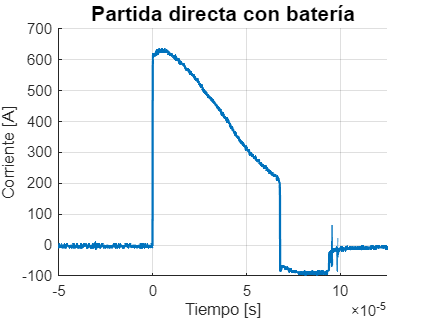

rSense = 1.5e-3;

data = readmatrix("2025-12-19_Battery_2/scope_12.csv", 'NumHeaderLines', 2);
time_1      = data(:, 1);
volt_1      = data(:, 2);
volt_1      = volt_1 / rSense; %Rsense corriente

clf %% clean figure

figure(3)
hold on 
grid on
% yyaxis left
plot(time_1,volt_1,'LineStyle', '-', 'LineWidth', 1.5)
% ylim([-5 30]);
ylabel("Corriente [A]");

xlabel("Tiempo [s]");
xlim([-0.5e-4 1.25e-4])
title("Partida directa con batería",'FontSize',14);
% subtitle(plotSubTitle,'FontSize',8);

hold off
exportgraphics(gcf,"Figuras/inrush_switch.png");

# Pre partida suave

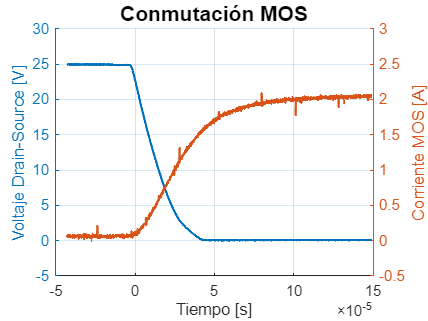

data = readmatrix("2025-12-22_Convertidores_4/scope_3.csv", 'NumHeaderLines', 2);
time_1      = data(:, 1);
volt_1      = data(:, 2);
volt_1      = max(volt_1)-volt_1; %inverte corriente
current_1   = data(:, 3);
current_1   = current_1 + abs(min(current_1)); %inverte corriente

data = readmatrix("2025-12-22_Convertidores_4/scope_4.csv", 'NumHeaderLines', 2);
time_2      = data(:, 1);
volt_2      = data(:, 2);
volt_2      = max(volt_2) - volt_2; %inverte corriente
current_2   = data(:, 3);
current_2   = current_2+abs(min(current_2)); %inverte corriente

clf %% clean figure

figure(4)
hold on 
grid on
yyaxis left
plot(time_1,volt_1,'LineStyle', '-', 'LineWidth', 1.5)
ylim([-5 30]);
ylabel("Voltaje Drain-Source [V]");

yyaxis right
plot(time_1,current_1,'LineStyle', '-', 'LineWidth', 1.5)
ylim([-0.5 3]);
ylabel("Corriente MOS [A]");

xlabel("Tiempo [s]");
xlim([-5e-5 15e-5])
title("Conmutación MOS",'FontSize',14);
% subtitle(plotSubTitle,'FontSize',8);

hold off
exportgraphics(gcf,"Figuras/ss_test11.png");

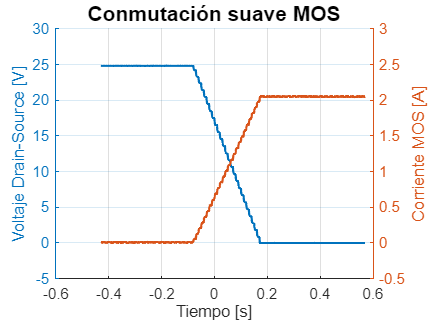


clf %% clean figure
figure(5)
hold on 
grid on
yyaxis left
scp21 = plot(time_2,volt_2,'LineStyle', '-', 'LineWidth', 1.5);
ylim([-5 30]);
ylabel("Voltaje Drain-Source [V]");

yyaxis right
scp22 = plot(time_2,current_2,'LineStyle', '-', 'LineWidth', 1.5);
ylim([-0.5 3]);
ylabel("Corriente MOS [A]");

xlabel("Tiempo [s]");
title("Conmutación suave MOS",'FontSize',14);
% subtitle(plotSubTitle,'FontSize',8);

% % 0 crossing alignment
% ax = gca;
% yl = ax.YAxis(1).Limits; % Left limits [min max]
% yr = ax.YAxis(2).Limits; % Right limits [min max]
% 
% % 3. Calculate the ratio of (positive range / total span)
% % This tells us where 'zero' currently sits as a percentage of the height
% ratioL = yl(2) / (yl(2) - yl(1));
% ratioR = yr(2) / (yr(2) - yr(1));
% 
% % 4. Adjust to the more 'constrained' ratio to align zeros
% if ratioL > ratioR
%     % Adjust Right axis to match Left
%     new_min = yr(2) - (yr(2) / ratioL);
%     yyaxis right;   ylim([new_min, yr(2)]);
% else
%     % Adjust Left axis to match Right
%     new_min = yl(2) - (yl(2) / ratioR);
%     yyaxis left;    ylim([new_min, yl(2)]);
% end

hold off
exportgraphics(gcf,"Figuras/ss_test12.png");

# Partida Suave

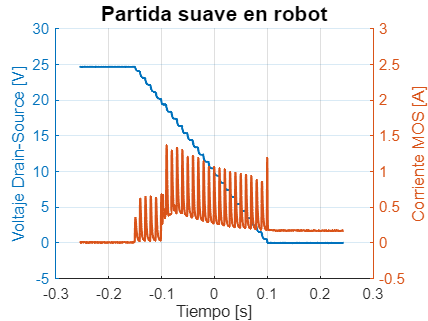


data = readmatrix("2025-12-22_Convertidores_4/scope_10.csv", 'NumHeaderLines', 2);
time_3      = data(:, 1);
volt_3      = data(:, 2);
volt_3      = max(volt_3) - volt_3; %inverte corriente
current_3   = data(:, 3);
current_3   = current_3+abs(min(current_3)); %inverte corriente

clf %% clean figure

figure(6)
hold on 
grid on
yyaxis left
plot(time_3,volt_3,'LineStyle', '-', 'LineWidth', 1.5)
ylim([-5 30]);
ylabel("Voltaje Drain-Source [V]");

yyaxis right
plot(time_3,current_3,'LineStyle', '-', 'LineWidth', 1.5)
ylim([-0.5 3]);
ylabel("Corriente MOS [A]");

xlabel("Tiempo [s]");
% xlim([-5e-5 15e-5])
title("Partida suave en robot",'FontSize',14);
% subtitle(plotSubTitle,'FontSize',8);
hold off
exportgraphics(gcf,"Figuras/ss_on11.png");

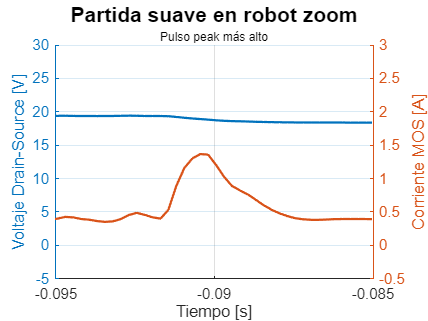


%Zoom
figure(7)
hold on 
grid on
yyaxis left
plot(time_3,volt_3,'LineStyle', '-', 'LineWidth', 1.5)
ylim([-5 30]);
ylabel("Voltaje Drain-Source [V]");

yyaxis right
plot(time_3,current_3,'LineStyle', '-', 'LineWidth', 1.5)
ylim([-0.5 3]);
ylabel("Corriente MOS [A]");

xlabel("Tiempo [s]");
xlim([-0.095 -0.085])
title("Partida suave en robot zoom",'FontSize',14);
subtitle("Pulso peak más alto",'FontSize',8);

hold off
exportgraphics(gcf,"Figuras/ss_on12.png");